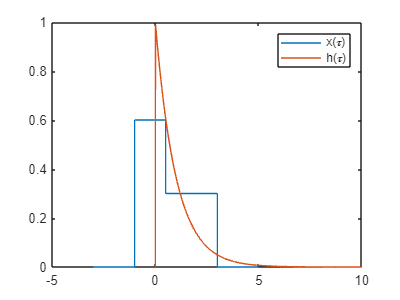

th1 = 0:0.01:10;
th = [0 th1];
h1 = exp(-th1).*heaviside(th1);
h = [0 h1];

tx1 = -1:0.01:0.5;
tx2 = 0.5:0.01:3;
tx3 = 3:0.01:5;
tx4 = -3:0.01:-1;
x1 = ones(size(tx1)) * 0.6;
x2 = ones(size(tx2)) * 0.3;
x3 = zeros(size(tx3));
x4 = zeros(size(tx4));
x = [x4 x1 x2 x3];
tx = [tx4 tx1 tx2 tx3];
figure 
plot(tx, x, th, h)
legend("x(\tau)", "h(\tau)")

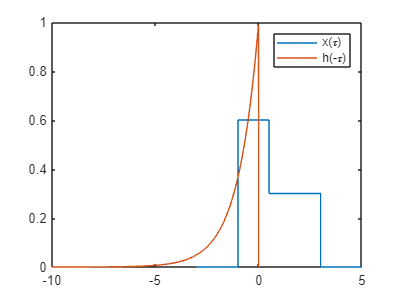


figure
plot(tx, x, -th, h)
legend("x(\tau)", "h(-\tau)")

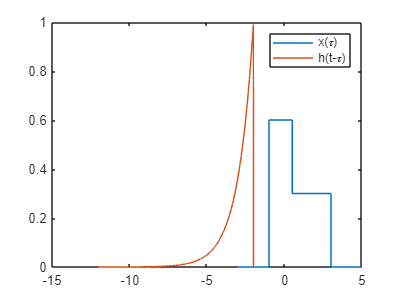


%Primeiro estagio
t = -2;
figure
plot(tx, x, t-th, h)
legend("x(\tau)", "h(t-\tau)")

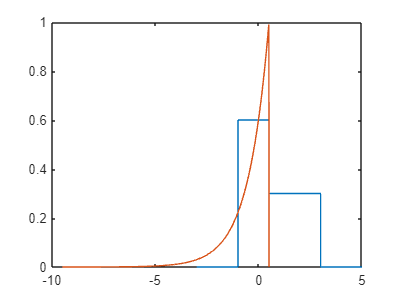


%Segundo estagio 
t = 0.5;
figure
plot(tx, x, t-th, h)

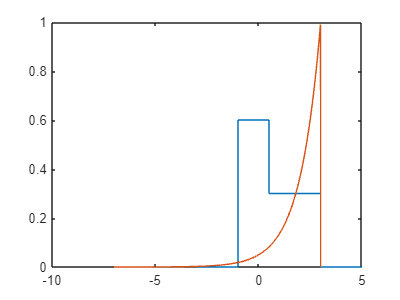


%Terceiro estagio 
t = 3;
figure
plot(tx, x, t - th, h)

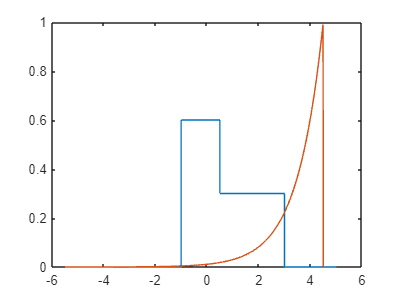


%Quarto estagio 
t = 4.5;
figure
plot(tx, x, t - th, h)


syms t r
f = 0.18*exp(t-r);
int(f, r, 0, t)

$$ans = \frac{9\,\mathrm{e}}{50}-\frac{9}{50}$$


int(f, r, t-1, t)

